clear
close all
hold off


En este código se va a implementar el método de Quasi-Newton para dos dimensiones. A continuación se determinan las condiciones iniciales y las constantes.

N=12; %Número de robots (a partir de N=6 buena aproximación)
iteration=51; %Número de iteraciones
step_size=0.1;
D=5; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0_initial=[20;20]; %Posición del centro inicial (initial guess)
r0=[0 0]'; %Centro de contaminación
e=[1;0];

w0=1; %Movimiento circular de un radián por segundo

colors=["ob","ok","or","oy","og","om","oc","ob"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0_initial;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
simulation=5; %número de simulaciones
mod_rc=zeros(iteration-1,simulation);
w0=1; %Movimiento circular de un radián por segundo
k=1.1; %Valor para el line search inexacto
H_0=eye(2); %Hessiano inicial para la iteración
I=eye(2);
v=2;
delta=0.1;

c1=10^-4;
c2=0.9; %Parámetros para el line search (c2=0.7 da solución rápida, valores más bajos resultan en un tiempo de computación notable)


Implementación del ruido:

%Se aplica el método del gradiente
for ki=1:simulation
    c0=c0_initial;
    for i=1:iteration-1
        %Se hacen las medias para ajustar mejor los valores H y de gradiente
        for j=1:100
            grad_centr_est(:,j)=gradient_point2D_ruido(c(:,i),t(i),N,D,S,w0,v,delta);
        end
        media1=mean(grad_centr_est(1,:));
        media2=mean(grad_centr_est(2,:));
        grad_centr(:,i)=[media1;media2];
        alpha1=1; 
        p(:,i)=-H_0(:,:,i)*grad_centr(:,i); %Dirección descendente
        steplengthParam=[c1,c2,alpha1,k];
        [alpha(i),u(i)]=alpha_strongWolfe_RUIDO(c(:,i), p(:,i), steplengthParam,t(i),N,D,S,w0,v,delta);        
        c(:,i+1)=c(:,i)-alpha(i)*H_0(:,:,i)*grad_centr(:,i);
        %Se hace la aproximación otra vez
        for j=1:100
            grad_centr_est_2(:,j)=gradient_point2D_ruido(c(:,i+1),t(i+1),N,D,S,w0,v,delta);
        end
        media1_n=mean(grad_centr_est_2(1,:));
        media2_n=mean(grad_centr_est_2(2,:));
        grad_centr(:,i+1)=[media1_n;media2_n];
        x_k1=c(:,i+1);
        x_k=c(:,i);
        s_k=x_k1-x_k;
        q_k=grad_centr(:,i+1)-grad_centr(:,i);
        B_k=(I-(s_k*q_k'/(q_k'*s_k)))*H_0(:,:,i)*(I-(q_k*s_k'/(q_k'*s_k)))+s_k*s_k'/(q_k'*s_k); %Hessiano invertido
        H_0(:,:,i+1)=B_k;       
        
        c0=c(:,i);
        mod_r_c(i)=norm(c0-r0);
    end
    mod_rc(:,ki)=mod_r_c;
    num_iteraciones(ki)=sum(u) %número de iteraciones
end

num_iteraciones = 51343

num_iteraciones =        51343       48365


num_iteraciones =        51343       48365       60546


num_iteraciones =        51343       48365       60546       45271


num_iteraciones =        51343       48365       60546       45271       54445


Representación de la media y la desviación estándar:

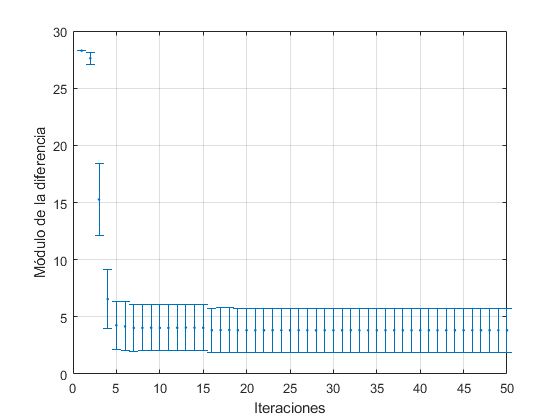

for h=1:iteration-1
    media(h)=mean(mod_rc(h,:));
    desv_std(h)=std(mod_rc(h,:));
end
errorbar(1:iteration-1,media,desv_std,'.')

xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on

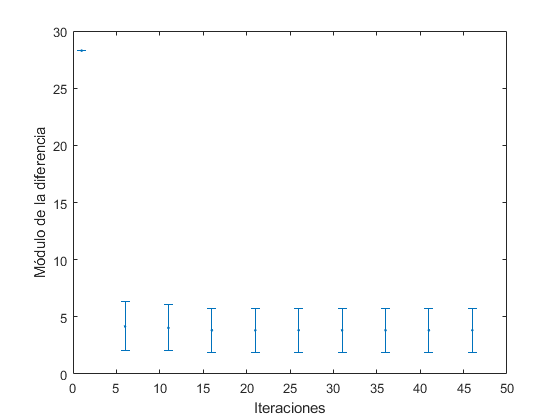


puntos=1:5:iteration-1;
errorbar(puntos,media(puntos),desv_std(puntos),'.')
xlabel('Iteraciones')
ylabel('Módulo de la diferencia')

xaxis

Undefined function or variable 'xaxis'.

grid on
iteracione_media=mean(num_iteraciones)
